clear; close all; imtool close all; clc;rng('default')

## 学習済みネットワークの読み込み

load('myalexnet')

## Autodiffにかけられるようにdlnetworkに変更

lgraph = layerGraph(convnet.Layers); %
Outputlayer =  lgraph.Layers(end);
newlgraph = removeLayers(lgraph,lgraph.Layers(end).Name); % calssificationの層だけ取る
net2 = dlnetwork(newlgraph); % dlnetworkに変更

softmaxlayer = 'prob' ; % 予測確率が出てくる最後のレイヤを指定
activationlayer = 'relu5'; % MAPを適用するレイヤを指定

## Use a while loop to read and play the video frames

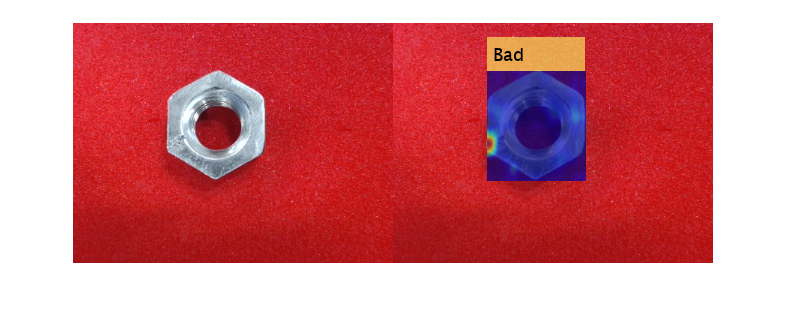

labeltbl = {'Bad';'Good'};
colortbl = [255 255 102; 73 6 248];
img = imread('ng1.png');% 画像の取り込み
hsv = rgb2hsv(img); % HSV色空間へ変更
th = otsuthresh(imhist(hsv(:,:,2))); % 彩度に対してThreshを決定する
bw = hsv(:,:,2) > th; % 彩度を閾値にして領域の切り出し
bw = bwareaopen(~bw,5000); % 5000より小さい領域は削除
bw = imclearborder(bw); % 画像境界と接するものは削除
stats = regionprops('table',bw,'BoundingBox'); % 境界ボックスの取り出し

if ~isempty(stats) % 領域が見つかった場合の処理
    bbox = int16(stats.BoundingBox); %
    img2 = imcrop(img,bbox); % 境界部分のみの切り出し
    img3 = imresize(img2,[227 227]); % ネットワークと同じサイズに変更
    [class,score] = classify(convnet,img3); % 推論
    img4 = dlarray(single(img3),'SSC');
    % 指定レイヤの出力とGradientをとる
    [conv_output,gradients] = dlfeval(@Gradient_function,net2,img4,softmaxlayer,activationlayer,class);
    % 得られた出力から演算でヒートマップを作製
    gradcam = sum(conv_output .* mean(gradients, [1 2]), 3); % GradientのGlobal average poolingし出力とかけ和をとる
    gradcam = extractdata(gradcam); % single型で取り出し。
    gradcam = max(gradcam,0); % relu関数を適用
    gradcam = imresize(gradcam, [227 227], 'Method', 'bicubic'); % 画像サイズに合わせる
    
    HeatMap = map2jpg(gradcam, [], 'jet'); % ヒートマップ表示の画像データに変換する
    HeatMap = uint8((im2double(img3)*0.3+HeatMap*0.5)*255); % 元画像と重ね合わせる
    
    [~,idx]=max(score); % 判定のインデックスを取り出す
    out = insertObjectAnnotation(img, 'rectangle', bbox,... % マーカを画像につける
        labeltbl{idx}, 'FontSize', 18, 'Color', colortbl(idx,:)); %
    out(bbox(2):bbox(2)+bbox(4),bbox(1):bbox(1)+bbox(3),:) = imresize(HeatMap,[bbox(4)+1 bbox(3)+1]);  % HeatMapを重ね合わせた画像に置き換える
    
else
    out = img; % 領域か見つからなければそのまま表示する
end
out2 = [img out]; % 元画像と結果を横方向に結合する
imshow(out2);shg

function [conv_output,gradients] = Gradient_function(net2,I2,softmaxlayer,activationlayer,class)
[scores,conv_output] = predict(net2, I2, 'Outputs', {softmaxlayer, activationlayer}); % 予測確率とMAPを作る層までの出力を得る
loss = scores(class); % 指定したクラスのスコアをとる
gradients = dlgradient(loss,conv_output); % MAPを作る層でのgradientをとる
gradients = gradients / (sqrt(mean(gradients.^2,'all')) + 1e-5); % 正規化する
end

% ヒートマップに変換する関数
function img = map2jpg(imgmap, range, colorMap)
imgmap = double(imgmap);
if(~exist('range', 'var') || isempty(range))
    range = [min(imgmap(:)) max(imgmap(:))];
end

heatmap_gray = mat2gray(imgmap, range);
heatmap_x = gray2ind(heatmap_gray, 256);
heatmap_x(isnan(imgmap)) = 0;

if(~exist('colorMap', 'var'))
    img = ind2rgb(heatmap_x, jet(256));
else
    img = ind2rgb(heatmap_x, eval([colorMap '(256)']));
end
end

%

*Copyright 2019 The MathWorks, Inc.*